# Linearity of Speed to EEG

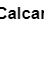

Unable to resolve the name 'TMP_FOOOF_T.design_id'.

%% PREDICTORS: SPEED. RESPONSE: BRAIN ACTIVITY, TEST FOR LINEARITY
% STATS_OUT = [];
% im_resize= 1.2;
VIOLIN_BOTTOM = 0.65;
% AX_H  = 0.2;
% AX_W = 0.25;
DO_PLOT_GROUPS = true;
% REGRESS_TXT_SIZE = 8;
% REGRESS_TXT_XMULTI = 0.9;
% REGRESS_TXT_YMULTI = 0.9;
MEASURE_NAME_LABS = {'Mean \theta','Mean \alpha','Mean \beta'};
im_resize = 0.8;
AX_W = 0.35;
AX_H = 0.25;
% GROUP_SHORTS = {'YA','HO','FO'};
% GROUP_MARKERS = {'o','x','*'};
tmp_savedir = [save_dir filesep 'Pspeed-Reeg-linearity'];
mkdir(tmp_savedir);
for cl_i = 1:length(clusters)
    %
    atlas_name = atlas_name_store{cl_i};
    fig = figure('color','white','renderer','Painters');
    sgtitle(atlas_name,'FontName',PLOT_STRUCT.font_name,'FontSize',14,'FontWeight','bold','Interpreter','none');
    set(fig,'Units','inches','Position',[0.5,0.5,6.5,9])
    set(fig,'PaperUnits','inches','PaperSize',[1 1],'PaperPosition',[0 0 1 1])
    set(gca,AXES_DEFAULT_PROPS{:})
    vert_shift = 0;
    for des_i = 2 %## JUST SPEED
        %##
        horiz_shift = 0;
        switch des_i
            case 1
                color_dark = COLORS_MAPS_TERRAIN;
                color_light = COLORS_MAPS_TERRAIN;
                GROUP_CMAP_OFFSET = [0,0.1,0.1];
                xtick_label_g = {'flat','low','med','high'};
            case 2
                color_dark = COLOR_MAPS_SPEED;
                color_light = COLOR_MAPS_SPEED+0.15;
                GROUP_CMAP_OFFSET = [0.15,0,0];
                xtick_label_g = {'0.25','0.50','0.75','1.0'};
        end
        for meas_i = 1:length(measure_name_plot)
            measure_name = measure_name_plot{meas_i};
            inds = TMP_FOOOF_T.design_id == designs(des_i) & TMP_FOOOF_T.cluster_id == clusters(cl_i);
            T_vals_plot = TMP_FOOOF_T(inds,:);
            T_vals_plot.cond_char = double(string(T_vals_plot.cond_char));
            subjects = unique(T_vals_plot.subj_char);
            conds = unique(T_vals_plot.cond_id);
            %##
            STATS_STRUCT = struct('anova',{{}},...
                          'anova_grp',{{}},...
                          'pvals',{{}},...
                          'pvals_pairs',{{}},...
                          'pvals_grp',{{}},...
                          'pvals_grp_pairs',{{}},...
                          'regress_pval',{{}},...
                          'regress_line',{{}},...
                          'r2_coeff',{{}},...
                          'regress_xvals',0);
            VIOLIN_PARAMS = {'width',0.1,...
                'ShowWhiskers',false,'ShowNotches',false,'ShowBox',true,...
                'ShowMedian',true,'Bandwidth',0.15,'QuartileStyle','shadow',...
                'HalfViolin','full','DataStyle','scatter','MarkerSize',8,...
                'EdgeColor',[0.5,0.5,0.5],'ViolinAlpha',{0.2 0.3}};
            PLOT_PARAMS = struct('color_map',color_dark,...
                'cond_labels',unique(T_vals_plot.cond_char),'group_labels',unique(T_vals_plot.group_char),...
                'cond_offsets',[-0.35,-0.1,0.15,0.4],'group_offsets',[0.125,0.475,0.812],...
                'y_label',measure_name,...
                'title',measure_name,'font_size',8,'ylim',[min(T_vals_plot.(measure_name))-std(T_vals_plot.(measure_name)),max(T_vals_plot.(measure_name))+3*std(T_vals_plot.(measure_name))],...
                'font_name','Arial','x_label','speed','do_combine_groups',~DO_PLOT_GROUPS);

            hold on;
            axax = group_violin(T_vals_plot,measure_name,'cond_char','group_char',...
                fig,...
                'VIOLIN_PARAMS',VIOLIN_PARAMS,...
                'PLOT_PARAMS',PLOT_PARAMS,...
                'STATS_STRUCT',STATS_STRUCT);
            %-
            hold on;
            cnt_g = 1;
            xtxt_shft = 0;
            ytxt_shft = 0; 
            xticks = get(axax,'XTick');
            for group_i = 1:length(groups)
                if DO_PLOT_GROUPS
                    inds = T_vals_plot.group_char == string(group_chars(group_i));
                    data = T_vals_plot(inds,:);
                else
                    data = T_vals_plot;
                end
                x_plot = xticks(cnt_g:cnt_g+length(conds)-1);
                y = data.(measure_name);
                x = data.cond_char;
                p2 = polyfit(x,y,2);
                v2 = polyval(p2,x);              % Evaluate
                p1 = polyfit(x,y,1);
                v1 = polyval(p1,x);              % Evaluate
                TSE = sum((v2 - y).^2)-sum((v1 - y).^2);         % Total Squared Error
                %-
                y_lim_calc = [min(y)-std(y),max(y)+3*std(y)];
                x = unique(data.cond_char);
                y = [];
                for i = 1:length(x)
                    y(i) = p2(1)*x(i)^2 + p2(2)*x(i) + p2(3);
                end
                plot(x_plot,y,...
                    'DisplayName',sprintf('polyfit^2'),...
                    'LineWidth',2,'LineStyle','-.','Color','k');
                hold on;
                x = unique(data.cond_char);
                y = [];
                for i = 1:length(x)
                    y(i) = p1(1)*x(i) + p1(2);
                end
                plot(x_plot,y,...
                    'DisplayName',sprintf('polyfit^2'),...
                    'LineWidth',2,'LineStyle','--','Color','k');
                hold on;
                eq = sprintf('y=(%0.1g)*x^2+(%0.1g)*x+(%0.1g)',p2(1),p2(2),p2(3));
                text(0.1+xtxt_shft,VIOLIN_BOTTOM-vert_shift+0.025+ytxt_shft,sprintf('TSE_{quad-lin}= %0.2g',TSE),...
                    'FontSize',6,...
                    'FontName',PLOT_PARAMS.font_name,...
                    'FontWeight','bold','Units','normalized');
                cnt_g = cnt_g + length(conds);
                xtxt_shft = xtxt_shft + 0.25;
                ytxt_shft = ytxt_shft + 0.1;
                if ~DO_PLOT_GROUPS
                    break;
                end
            end
            if meas_i == 1
                ylabel('10*log_{10}(Flattened PSD)');
            else
                ylabel('');
            end
            xlabel('Speed (m/s)');
            title(MEASURE_NAME_LABS{meas_i});
            set(gca,'FontWeight','bold');
            ylim(y_lim_calc)
            set(gca,'OuterPosition',[0,0,1,1]);
            set(gca,'Position',[0.075+horiz_shift,VIOLIN_BOTTOM+vert_shift,AX_W*im_resize,AX_H*im_resize]);  %[left bottom width height]
            % hold off;
            % set(gca,'Position',[horiz_shift+0.05,SCATTER_BOTTOM-vert_shift,AX_W*im_resize,AX_H*im_resize]);  %[left bottom width height]
            horiz_shift = horiz_shift + AX_H*im_resize + 0.115;
            hold on;
        end
        if DO_PLOT_GROUPS
            exportgraphics(fig,[tmp_savedir filesep sprintf('cl%s_speed-eeg-group_linearity.tiff',string(clusters(cl_i)))],'Resolution',300)
        else
            exportgraphics(fig,[tmp_savedir filesep sprintf('cl%s_speed-eeg_linearity.tiff',string(clusters(cl_i)))],'Resolution',300)
        end
        close(fig)
   end
end

# ANOVAs and Linear Models for Kinematics and Speed

%% PREDICTORS: SPEED CONDITION, RESPONSE: KINEMATICS, STATS TEST
STATS_OUT = [];
im_resize= 1.2;
VIOLIN_BOTTOM = 0.7;
AX_H  = 0.2;
AX_W = 0.25;
DO_PLOT_GROUPS = false;
tmp_savedir = [save_dir filesep 'Pspeed-Rkin'];
mkdir(tmp_savedir);
for var_i = 1:length(varnames)
    %
    vert_shift = 0;
    for des_i = 2 %## JUST SPEED
        %##
        horiz_shift = 0;
        switch des_i
            case 1
                color_dark = COLORS_MAPS_TERRAIN;
                color_light = COLORS_MAPS_TERRAIN;
                GROUP_CMAP_OFFSET = [0,0.1,0.1];
                xtick_label_g = {'flat','low','med','high'};
            case 2
                color_dark = COLOR_MAPS_SPEED;
                color_light = COLOR_MAPS_SPEED+0.15;
                GROUP_CMAP_OFFSET = [0.15,0,0];
                xtick_label_g = {'0.25','0.50','0.75','1.0'};
        end
        inds = TMP_FOOOF_T.design_id == designs(des_i);
        T_vals_plot = TMP_FOOOF_T(inds,:);
        subjects = unique(T_vals_plot.subj_char);
        conds = unique(T_vals_plot.cond_id);
        % groups = unique(T_vals_plot.group_id);
        t_tmp = [];
        for i = 1:length(subjects)
            ii = find(T_vals_plot.subj_char == subjects(i));
            tt = T_vals_plot(ii,:);
            for j = 1:length(conds)
                jj = find(tt.cond_id == conds(j));
                t_tmp = [t_tmp; tt(jj(1),:)];
            end
        end
        T_vals_plot = table(categorical(string(t_tmp.cond_char)),t_tmp.(varnames{var_i}),categorical(string(t_tmp.group_char)),...
           'VariableNames',{'cond_char',varnames{var_i},'group_char'});
        % T_vals_plot.cond_char = double(string(T_vals_plot.cond_char));
        try
            mod = sprintf('%s ~ 1 + %s',varnames{var_i},'cond_char');
            % stats_out = fitlme(T_vals_plot,mod);
            stats_out = fitlm(T_vals_plot,mod);
            % anova_out = anova(stats_out);
            out = anova(T_vals_plot,mod,'SumOfSquaresType',"three",'CategoricalFactors',{'cond_char'},...
                'ModelSpecification','linear');
            anova_out = out.stats();
            % anova_out = anovan(double(T_vals_plot.(varnames{var_i})),{T_vals_plot.cond_char},...
            %             'model','linear',...
            %             'model',1,...
            %             'sstype',3,...
            %             'varnames',strvcat('speed'));

            %## PRINT TABLES
            t = sprintf_table(anova_out);
            t.saveToFile([tmp_savedir filesep sprintf('%s_kinematics-speed_ANOVA.txt',varnames{var_i})]);
            t = sprintf_table(stats_out.Coefficients);
            t.saveToFile([tmp_savedir filesep sprintf('%s_kinematics-speed_LM.txt',varnames{var_i})]);
            %-
            R2 = stats_out.Rsquared.Adjusted;
            anova_p_var = anova_out.pValue(strcmp(anova_out.Properties.RowNames,'cond_char'));
            pval_inter = double(stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'(Intercept)')));
            pval_0p5 = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char_0.5'));
            pval_0p75 = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char_0.75'));
            pval_1p0 = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char_1.0'));
            % tstat_var = stats_out.Coefficients.tStat(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char'));
            % slope_var = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char')));
            inter_mn = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,'(Intercept)')));
        catch e
            fprintf('Error. Cluster %s\n\n%s\n',string(clusters(cl_i)),getReport(e))
            R2 = 0;
            pval = 1;
            slope = 0;
            inter = 0;
        end
        %##
            STATS_STRUCT = struct('anova',{{}},...
                          'anova_grp',{{}},...
                          'pvals',{{}},...
                          'pvals_pairs',{{}},...
                          'pvals_grp',{{}},...
                          'pvals_grp_pairs',{{}},...
                          'regress_pval',{{}},...
                          'regress_line',{{}},...
                          'r2_coeff',{{}},...
                          'regress_xvals',0);
        if DO_PLOT_GROUPS
            for gg = 1:length(groups)
                STATS_STRUCT.anova{gg}=anova_p_var;
                STATS_STRUCT.pvals_pairs{gg}={[1,1],[1,2],[1,3],[1,4]};
                STATS_STRUCT.pvals{gg}=[pval_inter,pval_0p5,pval_0p75,pval_1p0];
            end
        else
            STATS_STRUCT.anova{1}=anova_p_var;
            STATS_STRUCT.pvals_pairs{1}={[1,1],[1,2],[1,3],[1,4]};
            STATS_STRUCT.pvals{1}=[pval_inter,pval_0p5,pval_0p75,pval_1p0];
        end
        STATS_OUT = [STATS_OUT; STATS_STRUCT];
        % figure;
        VIOLIN_PARAMS = {'width',0.1,...
            'ShowWhiskers',false,'ShowNotches',false,'ShowBox',true,...
            'ShowMedian',true,'Bandwidth',0.15,'QuartileStyle','shadow',...
            'HalfViolin','full','DataStyle','scatter','MarkerSize',8,...
            'EdgeColor',[0.5,0.5,0.5],'ViolinAlpha',{0.2 0.3}};
        PLOT_PARAMS = struct('color_map',color_dark,...
            'cond_labels',unique(T_vals_plot.cond_char),'group_labels',unique(T_vals_plot.group_char),...
            'cond_offsets',[-0.35,-0.1,0.15,0.4],'y_label',varnames_labs{var_i},...
            'title',varnames_labs{var_i},'font_size',10,'group_offsets',[0.125,0.475,0.812],...
            'ylim',[min(T_vals_plot.(varnames{var_i}))-std(T_vals_plot.(varnames{var_i})),max(T_vals_plot.(varnames{var_i}))+3*std(T_vals_plot.(varnames{var_i}))],...
            'font_name','Arial','x_label','speed','do_combine_groups',~DO_PLOT_GROUPS);
        fig = figure('color','white','renderer','Painters');
        set(fig,'Units','inches','Position',[0.5,0.5,6.5,9])
        set(fig,'PaperUnits','inches','PaperSize',[1 1],'PaperPosition',[0 0 1 1])
        hold on;
        set(gca,AXES_DEFAULT_PROPS{:})
        axax = group_violin(T_vals_plot,varnames{var_i},'cond_char','group_char',...
            fig,...
            'VIOLIN_PARAMS',VIOLIN_PARAMS,...
            'PLOT_PARAMS',PLOT_PARAMS,...
            'STATS_STRUCT',STATS_STRUCT);
        set(axax,'OuterPosition',[0,0,1,1]);
        set(axax,'Position',[0.1+horiz_shift,VIOLIN_BOTTOM+vert_shift,AX_W*im_resize,AX_H*im_resize]);  %[left bottom width height]
        hold off;
        exportgraphics(fig,[tmp_savedir filesep sprintf('%s_kinematics-speed-factor_grouped.tiff',varnames{var_i})],'Resolution',300)
        % exportgraphics(fig,[tmp_savedir filesep sprintf('%s_kinematics-speed-contin_grouped.tiff',varnames{var_i})],'Resolution',300)
        close(fig)
        %- iterate
   end
end